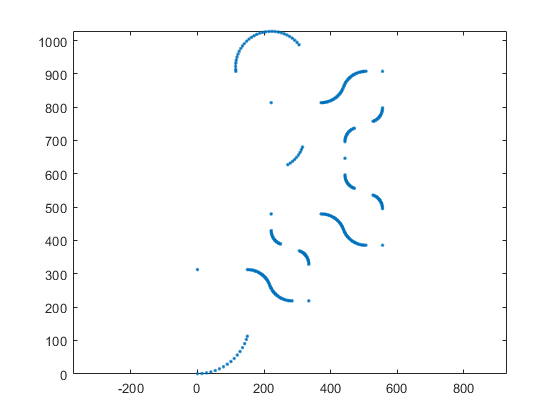

load trayectorianoSuave.mat
% trayectoria1
plot(x,y,'.')
axis('equal')

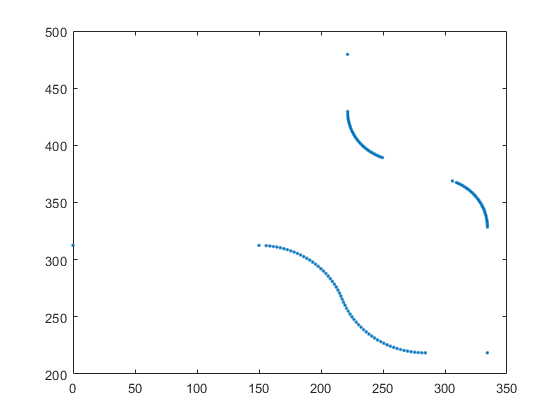


Aux=x<350;
Aux2=y<480 & y> 120;

plot(x(and(Aux,Aux2)),y(and(Aux,Aux2)),'.')

centro1 = [150,112.5]

centro1 =   150.0000  112.5000


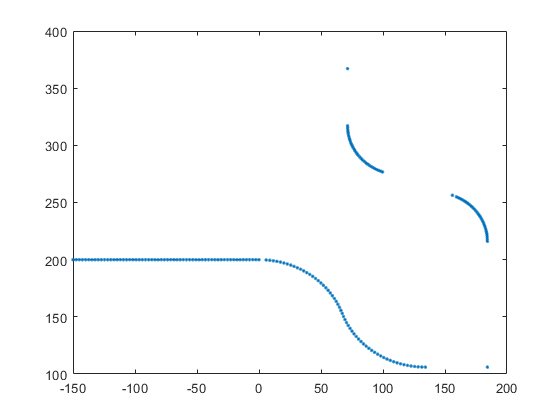


tx1=x(and(Aux,Aux2))-150;
ty1=y(and(Aux,Aux2))-112.5;

% como hace la trayectoria alrevez
tx1=tx1(end:-1:1);
ty1=ty1(end:-1:1);
% agregar puntos a linea rectas
% entre indices 1 y 2
Aux9=([tx1(2);ty1(2)]-[tx1(1);ty1(1)])*linspace(0,1,60)+[tx1(1);ty1(1)];

Ntx1=[Aux9(1,:)';tx1(3:end)];
Nty1=[Aux9(2,:)';ty1(3:end)];

plot(Ntx1,Nty1,'.')

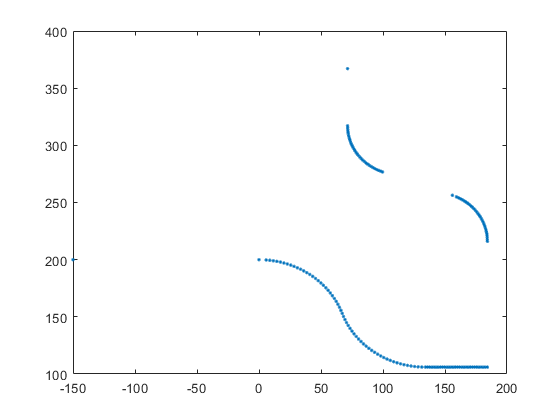


% indices 61 y 62
Aux10=([tx1(62);ty1(62)]-[tx1(61);ty1(61)])*linspace(0,1,30)+[tx1(61);ty1(61)];
N2tx1=[tx1(1:60);Aux10(1,:)';tx1(63:end)];
N2ty1=[ty1(1:60);Aux10(2,:)';ty1(63:end)];

plot(N2tx1,N2ty1,'.')

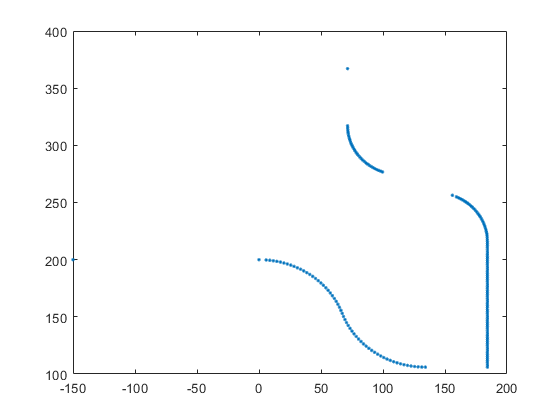

%ndices 62 y 63
Aux11=([tx1(63);ty1(63)]-[tx1(62);ty1(62)])*linspace(0,1,60)+[tx1(62);ty1(62)];
N3tx1=[tx1(1:61);Aux11(1,:)';tx1(64:end)];
N3ty1=[ty1(1:61);Aux11(2,:)';ty1(64:end)];

plot(N3tx1,N3ty1,'.')

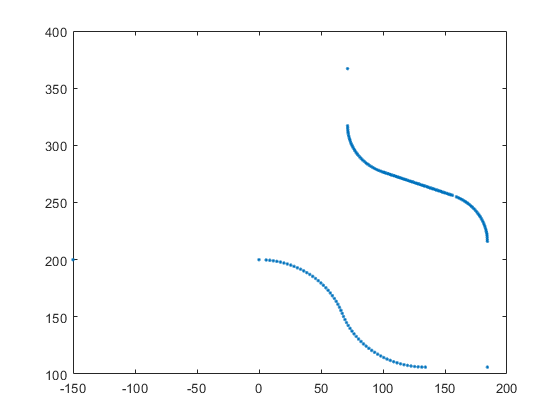

%ndices 92 y 93
Aux12=([tx1(93);ty1(93)]-[tx1(92);ty1(92)])*linspace(0,1,60)+[tx1(92);ty1(92)];
N4tx1=[tx1(1:91);Aux12(1,:)';tx1(94:end)];
N4ty1=[ty1(1:91);Aux12(2,:)';ty1(94:end)];

plot(N4tx1,N4ty1,'.')

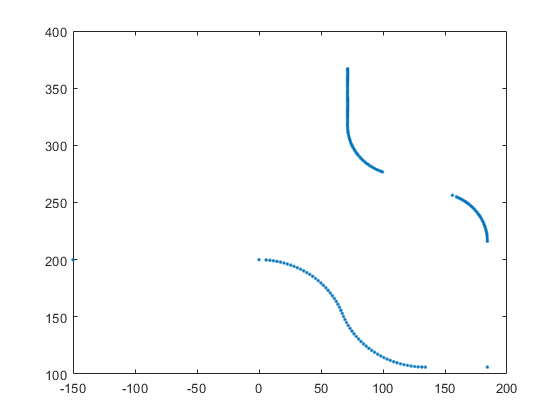

%ndices 123 y 124
Aux13=([tx1(124);ty1(124)]-[tx1(123);ty1(123)])*linspace(0,1,60)+[tx1(123);ty1(123)];
N5tx1=[tx1(1:122);Aux13(1,:)'];
N5ty1=[ty1(1:122);Aux13(2,:)'];
plot(N5tx1,N5ty1,'.')

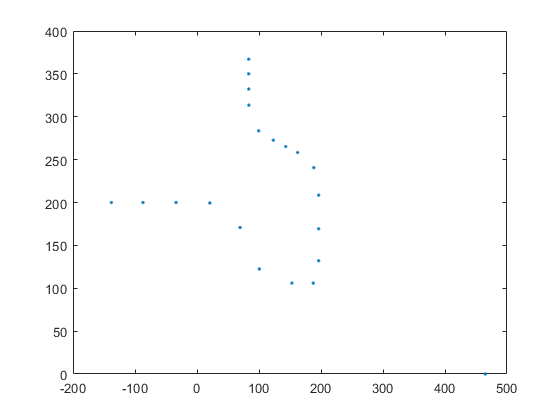


% trayectoria completa
NTx1=[Aux9(1,:)';tx1(3:60);Aux10(1,:)';Aux11(1,:)';tx1(63:91);Aux12(1,:)';tx1(94:122);Aux13(1,:)'];
NTy1=[Aux9(2,:)';ty1(3:60);Aux10(2,:)';Aux11(2,:)';ty1(63:91);Aux12(2,:)';ty1(94:122);Aux13(2,:)'];

x=NTx1(round(linspace(1,length(NTx1),20)));
y=NTy1(round(linspace(1,length(NTy1),20)));



x=x+12;
N2x=[465;x;465];
% Nx=Nx-12;

N2y=[0;y;0];
% Nx=[x];
% Ny=[y];

plot(Nx,Ny,'.')



% trayectoria 2
% plot(x(178+2:304),y(178+2:304),'.')